hemorRisTable = readtable('./Data/possible-hemorrhages-after-thrombectomy.csv')

hemorRisTable = 961×7 table
    Undersokningsnummer     Undersokningstypsnamn                                                            Fragestallning                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           Remisstext                                                                                        

risTable = readtable('./Data/all-post-thrombectomy-patients.csv')

risTable = 2050×7 table
    Undersokningsnummer     Undersokningstypsnamn                                           Fragestallning                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           Remisstext                                                                                                                             

question = risTable.Fragestallning;
freeText1 = risTable.Remisstext;
freeText2 = risTable.Prioanteckning;
freeText3 = risTable.Utlatandetext;
scanner = risTable.Modalitetsnamn;

freeTextTable = risTable(:,[4,5,6]);

% join all text here (columns must be cell arrays of characters)
colJoin =  rowfun(@(a,b,c) {strjoin([a,b,c],' ')}, freeTextTable, 'InputVariables', {'Remisstext','Prioanteckning','Utlatandetext'});
fullJoin = string(strjoin(colJoin{:,1},' '));

data = [colJoin,scanner];
data.Properties.VariableNames = ["Text","Label"];
data = convertvars(data,{'Text'},'string');
data

data = 2050×2 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    

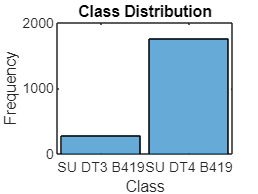

data.Label = categorical(data.Label);
figure
histogram(data.Label)
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

% Partition the data into a training partition and a held-out test set. Specify the holdout percentage to be 10%.

cvp = cvpartition(data.Label,'Holdout',0.1);
dataTrain = data(cvp.training,:);
dataTest = data(cvp.test,:);

% Extract the text data and labels from the tables.

textDataTrain = dataTrain.Text;
textDataTest = dataTest.Text;
YTrain = dataTrain.Label;
YTest = dataTest.Label;

documents = preprocessText(textDataTrain);

bag = bagOfWords(documents);
% Remove words from the bag-of-words model that do not appear more than two times in total. Remove any documents containing no words from the bag-of-words model, and remove the corresponding entries in labels.
bag = removeInfrequentWords(bag,2);
[bag,idx] = removeEmptyDocuments(bag);
YTrain(idx) = [];
bag

bag =   bagOfWords with properties:

          Counts: [1845×4431 double]
      Vocabulary: ["anamnes"    "kvinna"    "med"    "wake"    "stroke"    "funnen"    "pares"    "har"    "tablettbeh"    "hypertoni"    "dta"    "visat"    "tromb"    "nih"    "vid"    "inkomst"    "trombectomi"    "stentinläggning"    …    ]
        NumWords: 4431
    NumDocuments: 1845


XTrain = bag.Counts;
mdl = fitcecoc(XTrain,YTrain,'Learners','linear')

mdl =   CompactClassificationECOC
      ResponseName: 'Y'
        ClassNames: [SU DT3 B419    SU DT4 B419]
    ScoreTransform: 'none'
    BinaryLearners: {[1×1 ClassificationLinear]}
      CodingMatrix: [2×1 double]


  Properties, Methods


## Test classifier

% Preprocess the test data using the same preprocessing steps as the training data. Encode the resulting test documents as a matrix of word frequency counts according to the bag-of-words model.

documentsTest = preprocessText(textDataTest);
XTest = encode(bag,documentsTest);

% Predict the labels of the test data using the trained model and calculate the classification accuracy.

YPred = predict(mdl,XTest);
acc = sum(YPred == YTest)/numel(YTest)

acc = 0.9512

## LSTM classification

enc = wordEncoding(documents);

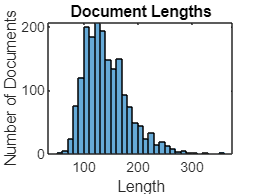

documentLengths = doclength(documents);
figure
histogram(documentLengths)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")

% Most of the training documents have fewer than x tokens. Use this as your target length for truncation and padding.
% Convert the documents to sequences of numeric indices using doc2sequence. To truncate or left-pad the sequences to have length x, set the 'Length' option to x.
% TODO: find this cutoff automatically using otsu-thresholding
sequenceLength = 200;
XTrain = doc2sequence(enc,documents,'Length',sequenceLength);
XTrain(1:5)

ans = 5×1 cell array
    {[                                                                                                                           0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 2 3 4 5 6 7 3 8 9 10 11 12 9 13 14 15 16 17 18 19 15 20 21 22 23 24 25 26 27 28 29 30 31 32 33 3 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 46 49 69 70 71 72 49 73 70 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 27 90 91 92 93 94 95 96 97 98 3 99 100 101 102 103 104 3 105 106 3 107 108 109 83 110 83 84 111 94 112 113 3 114 97 98 93 94 115 116]}
    {[                                      0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 117 118 119 120 121 122 123 124 125 3 126 127 27 128 129 27 130 94 131 132 133 123 134 135 136 137 135 138 139 140 130 94 127 118 141 3 31 49 33 142 3 143 144 1

% Define the LSTM network architecture.
% To input sequence data into the network, include a sequence input layer and set the input size to 1.
% Next, include a word embedding layer of dimension 50 and the same number of words as the word encoding.
% Next, include an LSTM layer and set the number of hidden units to 80.
% To use the LSTM layer for a sequence-to-label classification problem, set the output mode to 'last'.
% Finally, add a fully connected layer with the same size as the number of classes, a softmax layer, and a classification layer.
inputSize = 1;
embeddingDimension = 50;
numHiddenUnits = 80;

numWords = enc.NumWords;
numClasses = numel(categories(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   6×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 9240 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         2 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

YValidation = YTest;
documentsValidation = preprocessText(textDataTest); % TODO: change to validation later
XValidation = doc2sequence(enc,documentsValidation,'Length',sequenceLength);

options = trainingOptions('adam', ...
    'MiniBatchSize',16, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'Plots','training-progress', ...
    'Verbose',false);

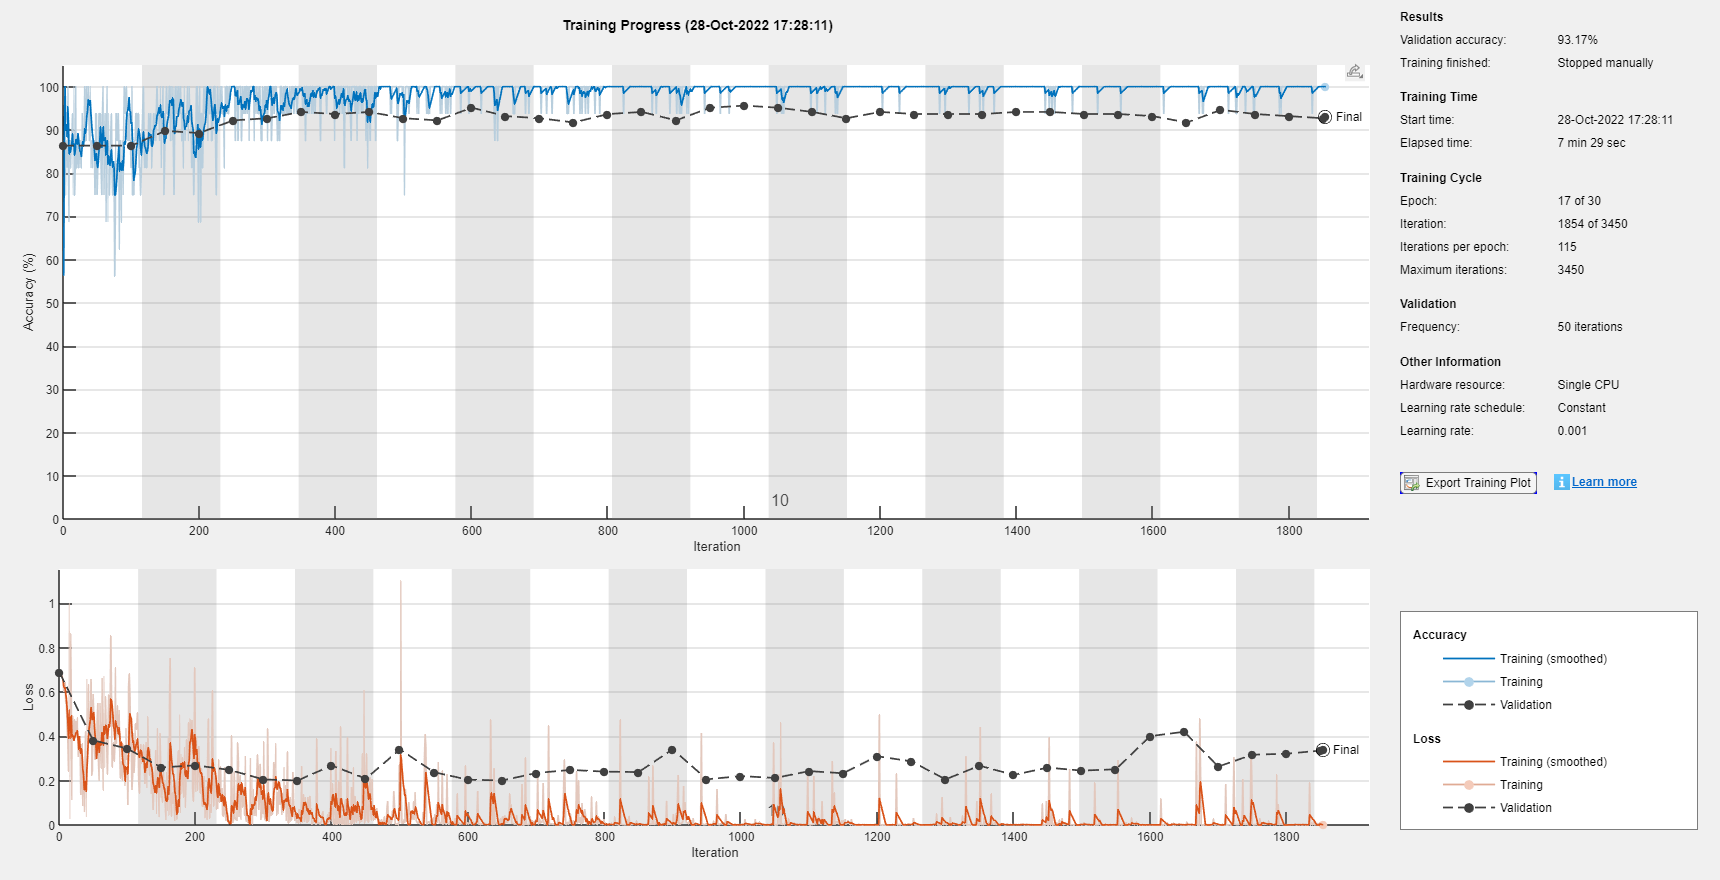

net = trainNetwork(XTrain,YTrain,layers,options);

## Rest

medCorpus = preprocessText(fullJoin);
rmWords = ["och","med","för","det","har","den","ett","en"];
medCorpus = removeWords(medCorpus,rmWords)

figure
wordcloud(medCorpus);

bag = bagOfWords(medCorpus);
M = tfidf(bag);
bagGrams2 = bagOfNgrams(medCorpus);

% Remove words from the bag-of-words model that do not appear more than two times in total. Remove any documents containing no words from the bag-of-words model, and remove the corresponding entries in labels.

% https://ch.mathworks.com/help/textanalytics/ug/create-simple-text-model-for-classification.html
% https://ch.mathworks.com/help/textanalytics/ug/classify-text-data-using-deep-learning.html
% https://ch.mathworks.com/help/textanalytics/ug/analyze-text-data-using-topic-models.html
% https://ch.mathworks.com/help/textanalytics/ug/analyze-text-data-using-multi-word-phrases.html

function documents = preprocessText(textData)           
    % Tokenize.
    documents = tokenizedDocument(textData);
    
    % Remove tokens containing digits.
    pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
    documents = replace(documents,pat,"");
    
    % Convert to lowercase.
    documents = lower(documents);
    
    % Remove short words.
    documents = removeShortWords(documents,2);
    
    % Remove stop words.
    documents = removeStopWords(documents);
end